## Design paramater of vehicle

clc
clear all

M=2000                % Mass of vehicle

M = 2000

Cr=0.009              % Rolling resistance coefficient

Cr = 0.0090

Cd=0.3                % Aerodynamic resistance coefficient

Cd = 0.3000

Af=4                  % Frontal area

Af = 4

Rw=0.300              % Wheel radius

Rw = 0.3000

g=9.81                % Acceleration due to gravity

g = 9.8100

rho=1.225             % Air density

rho = 1.2250

theta=0               % Gradient angle

theta = 0

## Design paramater of motor

ratio=5:0.5:15;       % Array of gear ratio of transmission drive
motorConfig=[1 2 3];  % Array motor configuration 
energy_consumption=zeros(length(ratio),length(motorConfig)); 

open('Technical_Test_2_model.slx')



for i=1:length(ratio)
    for j=1:length(motorConfig)
% Set gear ration and motor configuration
        set_param('Technical_Test_2_model/FMU','ratio',num2str(ratio(i)));  
        set_param('Technical_Test_2_model/FMU','motorConfig',num2str(motorConfig(j)));

        simOut=sim('Technical_Test_2_model.slx');
        energy_consumption(i,j)=simOut.Energy_Consumption_kWhr.Data(end);
    end
end

## Simulation Results 

% Printing Table of Energy Consumption
Motor_Configuration={'Motor Config-1','Motor Config-2','Motor Config-3'}

Motor_Configuration = 1×3 cell array
    {'Motor Config-1'}    {'Motor Config-2'}    {'Motor Config-3'}


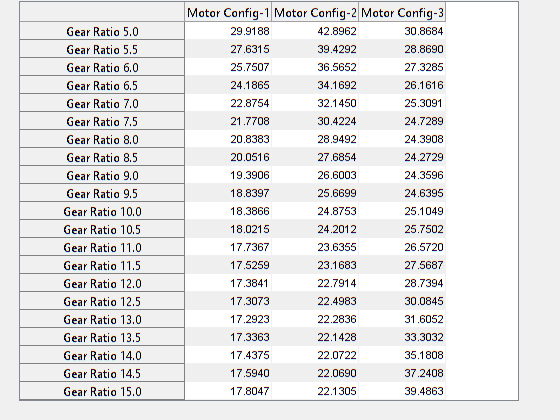

f=figure;
uitable(f,'Data',energy_consumption,'ColumnName',Motor_Configuration,'RowName',compose('Gear Ratio %.1f',ratio), ...
    'Position',[20 20 500 400]);


% Printing optimal value of Gear Ratio and Motor configuration
[min_energy,idx]=min(energy_consumption(:));
[row,col]=ind2sub(size(energy_consumption),idx);
optimal_gear_ratio=ratio(row);
optimal_motor_configuration=motorConfig(col);

fprintf('Optimal Gear Ratio: %.1f\n', optimal_gear_ratio);

Optimal Gear Ratio: 13.0


fprintf('Optimal Motor Configuration: %.d\n', optimal_motor_configuration);

Optimal Motor Configuration: 1


fprintf('Minimum Energy Consumption: %.3f\t kW-hr',min_energy);

Minimum Energy Consumption: 17.292	 kW-hr